# Simulink Aufgabe 2.1 Van der Pol

Der Van der Pol Generator ist ein schwingungsfähiges System mit nichtlinearer

Dämpfung und Selbsterregung. Das System kann mittels der folgenden Differentialgleichung

beschrieben werden. 


$$\ddot y - \mu(1-y^2)\dot y + y = 0$$


Das nichtlineare System zweiter Ordnung kann nun im Folgenden als System 

zweier nichtlinearer Differentialgleichungen beschrieben werden.


$$\dot y_1 = y_2 $$



$$\dot y_2 = \mu (1-y_1^2)y_2 -y_1$$


Dieses System soll im Folgenden simuliert werden. Verwenden Sie dazu ode45

auf einem Zeitintervall [0, 20] mit den Anfangswerten [2; 0]. Der Parameter 

𝜇 ist eins. Plotten sie anschließend die Lösung. Plotten Sie auch 𝑦_1 gegen 𝑦_2.

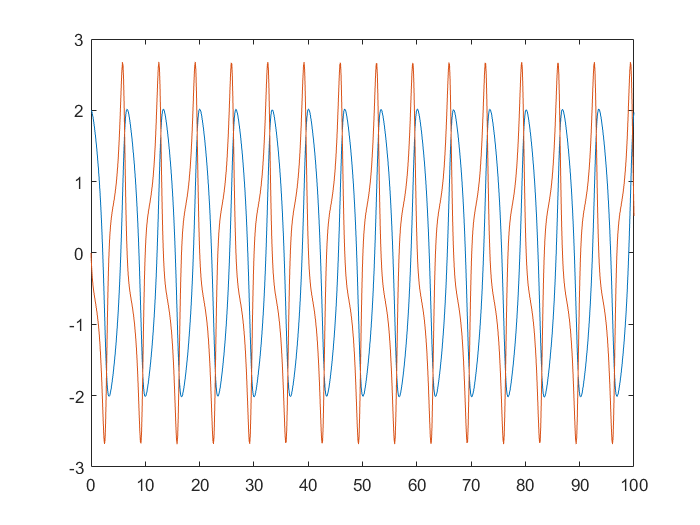

clc
close
clear

% Defining parameters
mue = 1;
tSpan = [0, 100];
y0 = [2; 0];

% Calling ode45 
[t, y]= ode45(@dglVanDerPol, tSpan, y0, [], mue);

% Plot solution
plot(t, y)

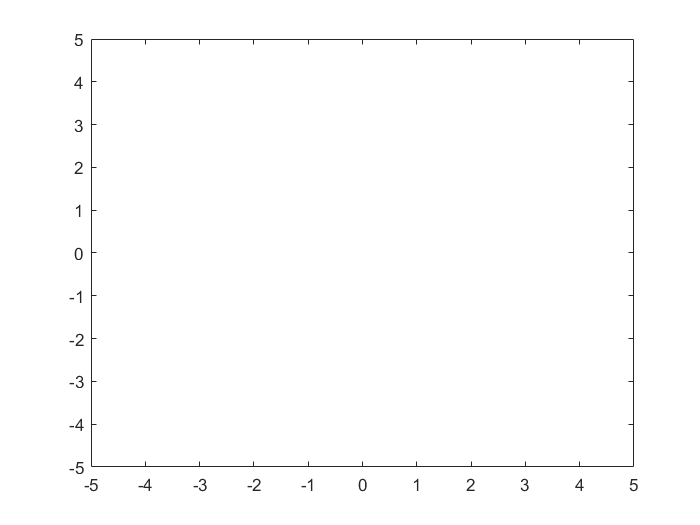

plot(y(1), y(2))
xlim([-5 5])
ylim([-5 5])